Now we can find Kc for the whole system. That can be done just by summing Kc matrices for all 3 legs

clc;
% transformation for end effector
T_tool = eye(4) ; T_base_x ; T_base_z ; T_base_y ;
% link 1 length
l_1 = 1;
% link 2 length
l_2 = 1;
%Rigid platform length
l_platform=0.1;
% thetas are equal to zero
t = zeros(1,13);
% working area
x = 200:10:250;
y = 200:10:250;
z = 200:10:250; 

2

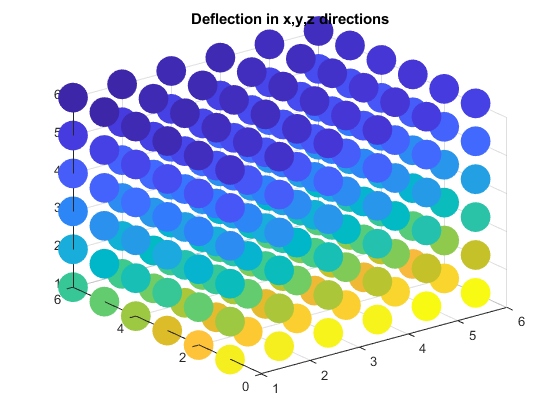

% loading on x,y,z directions 100Newton's for each
F = [100,100,100,0,0,0];

% 3d tensor for deflections
graph = zeros(length(x),length(y),length(z));


for i=1:length(x)
    for j = 1:length(y)
        for k = 1:length(z)
%             coordinates of end effector(pay attention that each
%             coordinate is divided to 1000), angles are equal to zero
            end_effector = [x(i)/1000,y(j)/1000,z(k)/1000,0,0,0];
  
%             inverse kinematics for leg 'x'
            q_1 = Inverse(end_effector,l_1,l_2,'x');
%           forward kinematics for leg 'x'
            T_x = FK(T_base_x,T_tool,q_1,t,l_1,l_2,l_platform,'x');
%             stiffness matrix for leg 'x'
            k1 = Virtual_joint(T_x,T_base_x,T_tool,q_1,t,l_1,l_2,l_platform,'x');

%             inverse kinematics for leg 'y'           
            q_2 = Inverse(end_effector,l_1,l_2,'y');
%           forward kinematics for leg 'y'
            T_y = FK(T_base_y,T_tool,q_2,t,l_1,l_2,l_platform,'y');
%             stiffness matrix for leg 'y'
            k2 = Virtual_joint(T_y,T_base_y,T_tool,q_2,t,l_1,l_2,l_platform,'y');
            
%             inverse kinematics for leg 'z'   
            q_3 = Inverse(end_effector,l_1,l_2,'z');
%           forward kinematics for leg 'z'
            T_x = FK(T_base_z,T_tool,q_3,t,l_1,l_2,l_platform,'z');
%             stiffness matrix for leg 'z'
            k3 = Virtual_joint(T_x,T_base_z,T_tool,q_3,t,l_1,l_2,l_platform,'z');
            
%             stiffness matrix for the whole robot equals sum of stiffness
%             matrices for each leg
            K = k1 + k2 + k3;
            
%             F = Kc * delta_t => delta_t = inv(Kc)*F 
% deflections
            dt=inv(K)*F';
            dr=sqrt(dt(1)^2+dt(2)^2 +dt(3)^2);
            graph(i,j,k) = dr;
        end
    end
end
%% here is only plotting part 
[x,y,z] = meshgrid(1:6,1:6,1:6);

figure

scatter3(x(:),y(:),z(:),500,graph(:),'filled');
title('Deflection in x,y,z directions')

3

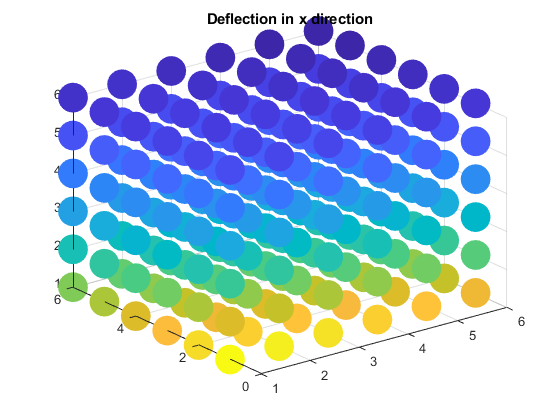

clc;
% transformation for end effector
T_tool = eye(4) ; T_base_x ; T_base_z ; T_base_y ;
% link 1 length
l_1 = 1;
% link 2 length
l_2 = 1;
% thetas are equal to zero
t = zeros(1,13);
% working area
x = 200:10:250;
y = 200:10:250;
z = 200:10:250; 
% loading on x direction 100Newton
F = [100,0,0,0,0,0];

% 3d tensor for deflections
graph = zeros(length(x),length(y),length(z));


for i=1:length(x)
    for j = 1:length(y)
        for k = 1:length(z)
%             coordinates of end effector(pay attention that each
%             coordinate is divided to 1000), angles are equal to zero
            end_effector = [x(i)/1000,y(j)/1000,z(k)/1000,0,0,0];
  
%             inverse kinematics for leg 'x'
            q_1 = Inverse(end_effector,l_1,l_2,'x');
%           forward kinematics for leg 'x'
            T_x = FK(T_base_x,T_tool,q_1,t,l_1,l_2,l_platform,'x');
%             stiffness matrix for leg 'x'
            k1 = Virtual_joint(T_x,T_base_x,T_tool,q_1,t,l_1,l_2,l_platform,'x');

%             inverse kinematics for leg 'y'           
            q_2 = Inverse(end_effector,l_1,l_2,'y');
%           forward kinematics for leg 'y'
            T_y = FK(T_base_y,T_tool,q_2,t,l_1,l_2,l_platform,'y');
%             stiffness matrix for leg 'y'
            k2 = Virtual_joint(T_y,T_base_y,T_tool,q_2,t,l_1,l_2,l_platform,'y');
            
%             inverse kinematics for leg 'z'   
            q_3 = Inverse(end_effector,l_1,l_2,'z');
%           forward kinematics for leg 'z'
            T_x = FK(T_base_z,T_tool,q_3,t,l_1,l_2,l_platform,'z');
%             stiffness matrix for leg 'z'
            k3 = Virtual_joint(T_x,T_base_z,T_tool,q_3,t,l_1,l_2,l_platform,'z');
            
%             stiffness matrix for the whole robot equals sum of stiffness
%             matrices for each leg
            K = k1 + k2 + k3;
            
%             F = Kc * delta_t => delta_t = inv(Kc)*F 
% deflections
            dt=inv(K)*F';
            dr=sqrt(dt(1)^2+dt(2)^2 +dt(3)^2);
            graph(i,j,k) = dr;
        end
    end
end
%% here is only plotting part 
[x,y,z] = meshgrid(1:6,1:6,1:6);

figure

scatter3(x(:),y(:),z(:),500,graph(:),'filled');
title('Deflection in x direction')

5

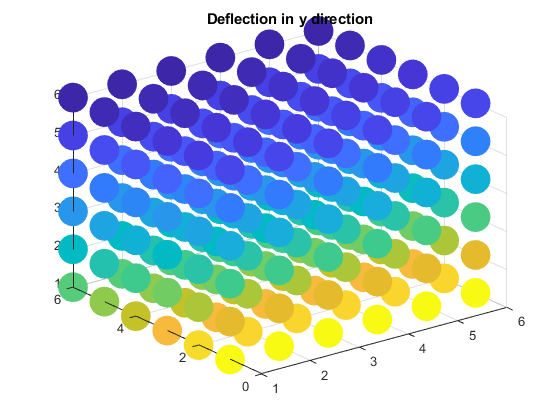

clc;
% transformation for end effector
T_tool = eye(4) ; T_base_x ; T_base_z ; T_base_y ;
% link 1 length
l_1 = 1;
% link 2 length
l_2 = 1;
% thetas are equal to zero
t = zeros(1,13);
% working area
x = 200:10:250;
y = 200:10:250;
z = 200:10:250; 
% loading on y direction 100Newton
F = [0,100,0,0,0,0];

% 3d tensor for deflections
graph = zeros(length(x),length(y),length(z));


for i=1:length(x)
    for j = 1:length(y)
        for k = 1:length(z)
%             coordinates of end effector(pay attention that each
%             coordinate is divided to 1000), angles are equal to zero
            end_effector = [x(i)/1000,y(j)/1000,z(k)/1000,0,0,0];
  
%             inverse kinematics for leg 'x'
            q_1 = Inverse(end_effector,l_1,l_2,'x');
%           forward kinematics for leg 'x'
            T_x = FK(T_base_x,T_tool,q_1,t,l_1,l_2,l_platform,'x');
%             stiffness matrix for leg 'x'
            k1 = Virtual_joint(T_x,T_base_x,T_tool,q_1,t,l_1,l_2,l_platform,'x');

%             inverse kinematics for leg 'y'           
            q_2 = Inverse(end_effector,l_1,l_2,'y');
%           forward kinematics for leg 'y'
            T_y = FK(T_base_y,T_tool,q_2,t,l_1,l_2,l_platform,'y');
%             stiffness matrix for leg 'y'
            k2 = Virtual_joint(T_y,T_base_y,T_tool,q_2,t,l_1,l_2,l_platform,'y');
            
%             inverse kinematics for leg 'z'   
            q_3 = Inverse(end_effector,l_1,l_2,'z');
%           forward kinematics for leg 'z'
            T_x = FK(T_base_z,T_tool,q_3,t,l_1,l_2,l_platform,'z');
%             stiffness matrix for leg 'z'
            k3 = Virtual_joint(T_x,T_base_z,T_tool,q_3,t,l_1,l_2,l_platform,'z');
            
%             stiffness matrix for the whole robot equals sum of stiffness
%             matrices for each leg
            K = k1 + k2 + k3;
            
%             F = Kc * delta_t => delta_t = inv(Kc)*F 
% deflections
            dt=inv(K)*F';
            dr=sqrt(dt(1)^2+dt(2)^2 +dt(3)^2);
            graph(i,j,k) = dr;
        end
    end
end
%% here is only plotting part 
[x,y,z] = meshgrid(1:6,1:6,1:6);

figure

scatter3(x(:),y(:),z(:),500,graph(:),'filled');
title('Deflection in y direction')

6

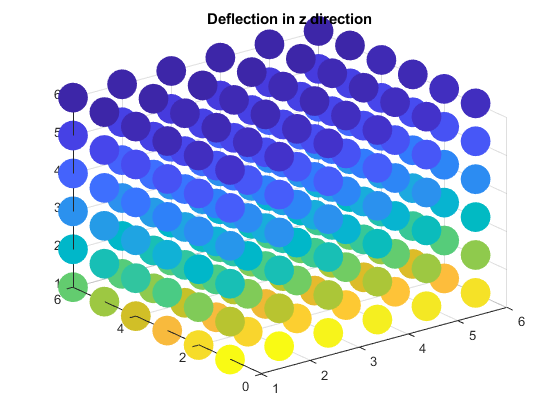

clc;
% transformation for end effector
T_tool = eye(4) ; T_base_x ; T_base_z ; T_base_y ;
% link 1 length
l_1 = 1;
% link 2 length
l_2 = 1;
% thetas are equal to zero
t = zeros(1,13);
% working area
x = 200:10:250;
y = 200:10:250;
z = 200:10:250; 
% loading on z direction 100Newton
F = [0,0,100,0,0,0];

% 3d tensor for deflections
graph = zeros(length(x),length(y),length(z));


for i=1:length(x)
    for j = 1:length(y)
        for k = 1:length(z)
%             coordinates of end effector(pay attention that each
%             coordinate is divided to 1000), angles are equal to zero
            end_effector = [x(i)/1000,y(j)/1000,z(k)/1000,0,0,0];
  
%             inverse kinematics for leg 'x'
            q_1 = Inverse(end_effector,l_1,l_2,'x');
%           forward kinematics for leg 'x'
            T_x = FK(T_base_x,T_tool,q_1,t,l_1,l_2,l_platform,'x');
%             stiffness matrix for leg 'x'
            k1 = Virtual_joint(T_x,T_base_x,T_tool,q_1,t,l_1,l_2,l_platform,'x');

%             inverse kinematics for leg 'y'           
            q_2 = Inverse(end_effector,l_1,l_2,'y');
%           forward kinematics for leg 'y'
            T_y = FK(T_base_y,T_tool,q_2,t,l_1,l_2,l_platform,'y');
%             stiffness matrix for leg 'y'
            k2 = Virtual_joint(T_y,T_base_y,T_tool,q_2,t,l_1,l_2,l_platform,'y');
            
%             inverse kinematics for leg 'z'   
            q_3 = Inverse(end_effector,l_1,l_2,'z');
%           forward kinematics for leg 'z'
            T_x = FK(T_base_z,T_tool,q_3,t,l_1,l_2,l_platform,'z');
%             stiffness matrix for leg 'z'
            k3 = Virtual_joint(T_x,T_base_z,T_tool,q_3,t,l_1,l_2,l_platform,'z');
            
%             stiffness matrix for the whole robot equals sum of stiffness
%             matrices for each leg
            K = k1 + k2 + k3;
            
%             F = Kc * delta_t => delta_t = inv(Kc)*F 
% deflections
            dt=inv(K)*F';
            dr=sqrt(dt(1)^2+dt(2)^2 +dt(3)^2);
            graph(i,j,k) = dr;
        end
    end
end
%% here is only plotting part 
[x,y,z] = meshgrid(1:6,1:6,1:6);

figure

scatter3(x(:),y(:),z(:),500,graph(:),'filled');
title('Deflection in z direction')